clc; close all; clear;
warning('off','all')

% Note download PlasmaFormulary - FundamentalPlasma()
addpath('C:\Users\rdatta\Dropbox (MIT)\PUFFIN\Codes\Other\PlasmaFormulary\')
addpath('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Codes/Other/PlasmaFormulary/')
load physicalConstants-SI.mat c
F = FundamentalPlasma();

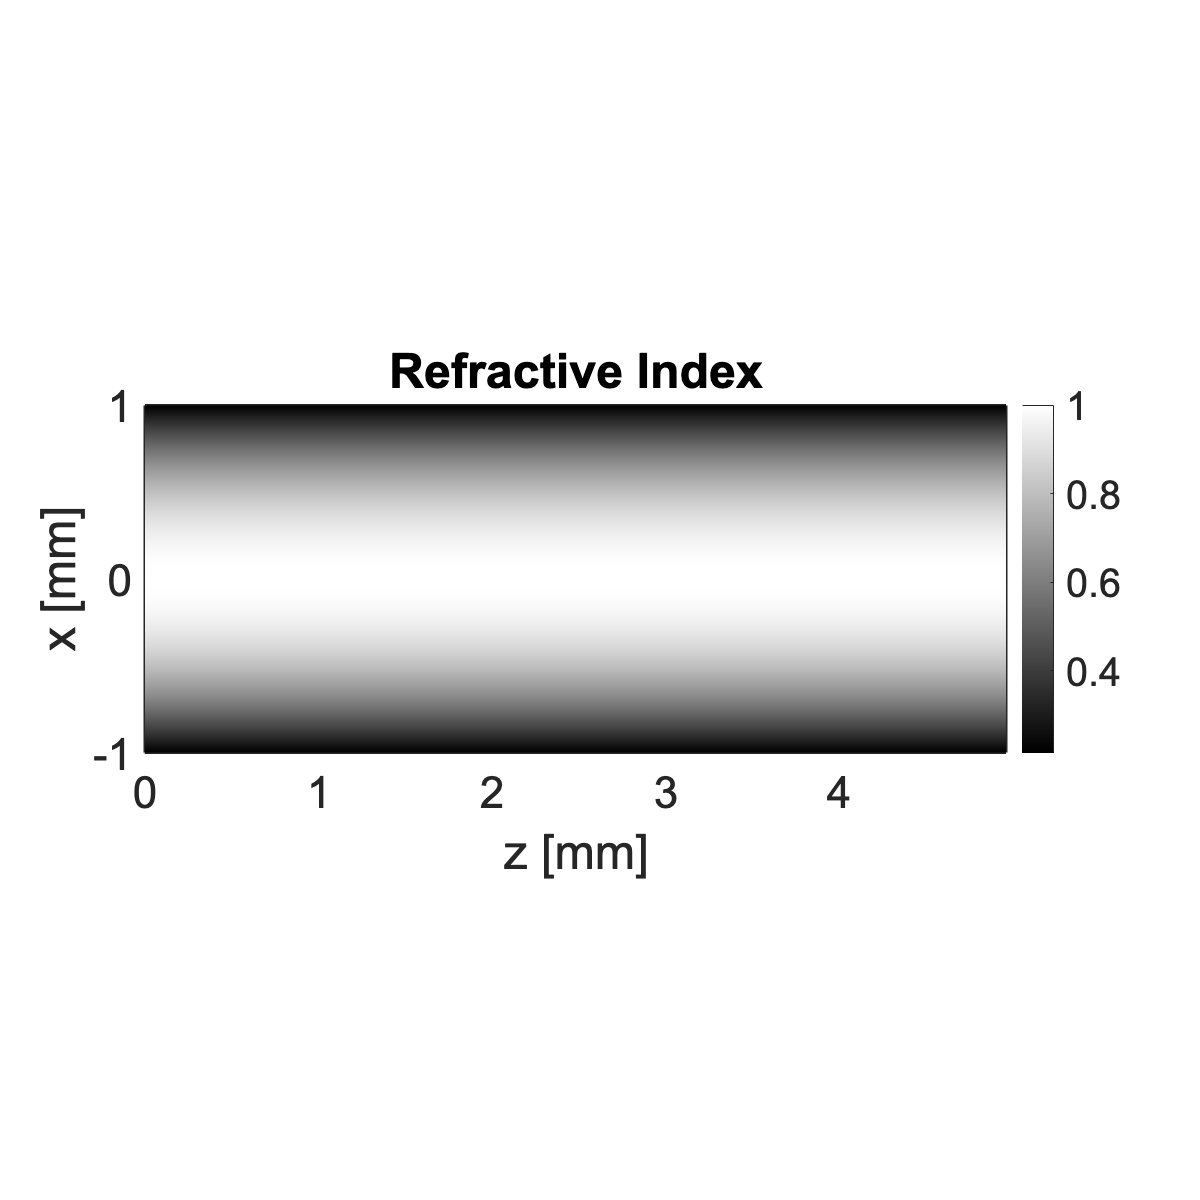

% Plasma Waveguide
t1 = HamTracer(532e-9,51,[-1e-3,1e-3],[0,5e-3]); % initialize tracer object

% Ref. idx (SELFOC)
A = pi / (2.5e-3);
nc = F.getOwavencrit(t1.lam*100); % cm^{-3}
ne = nc * (1 - (1-A^2/2 .* t1.xx.^2).^2); % cm^-3

N = t1.getOwaveN(ne); % refractive idx
t1 = t1.setN(N);

% Solve
xi = linspace(-0.2e-3,0.2e-3,10);
zi = 0 * ones(size(xi));
thi = 0 * ones(size(xi));
% thi = rand(size(xi))/10;

tmax = 20 * 2e-3 / c * 2;
t1 = t1.solve(xi,zi,thi,tmax,tmax/200);

figure
t1.showN()

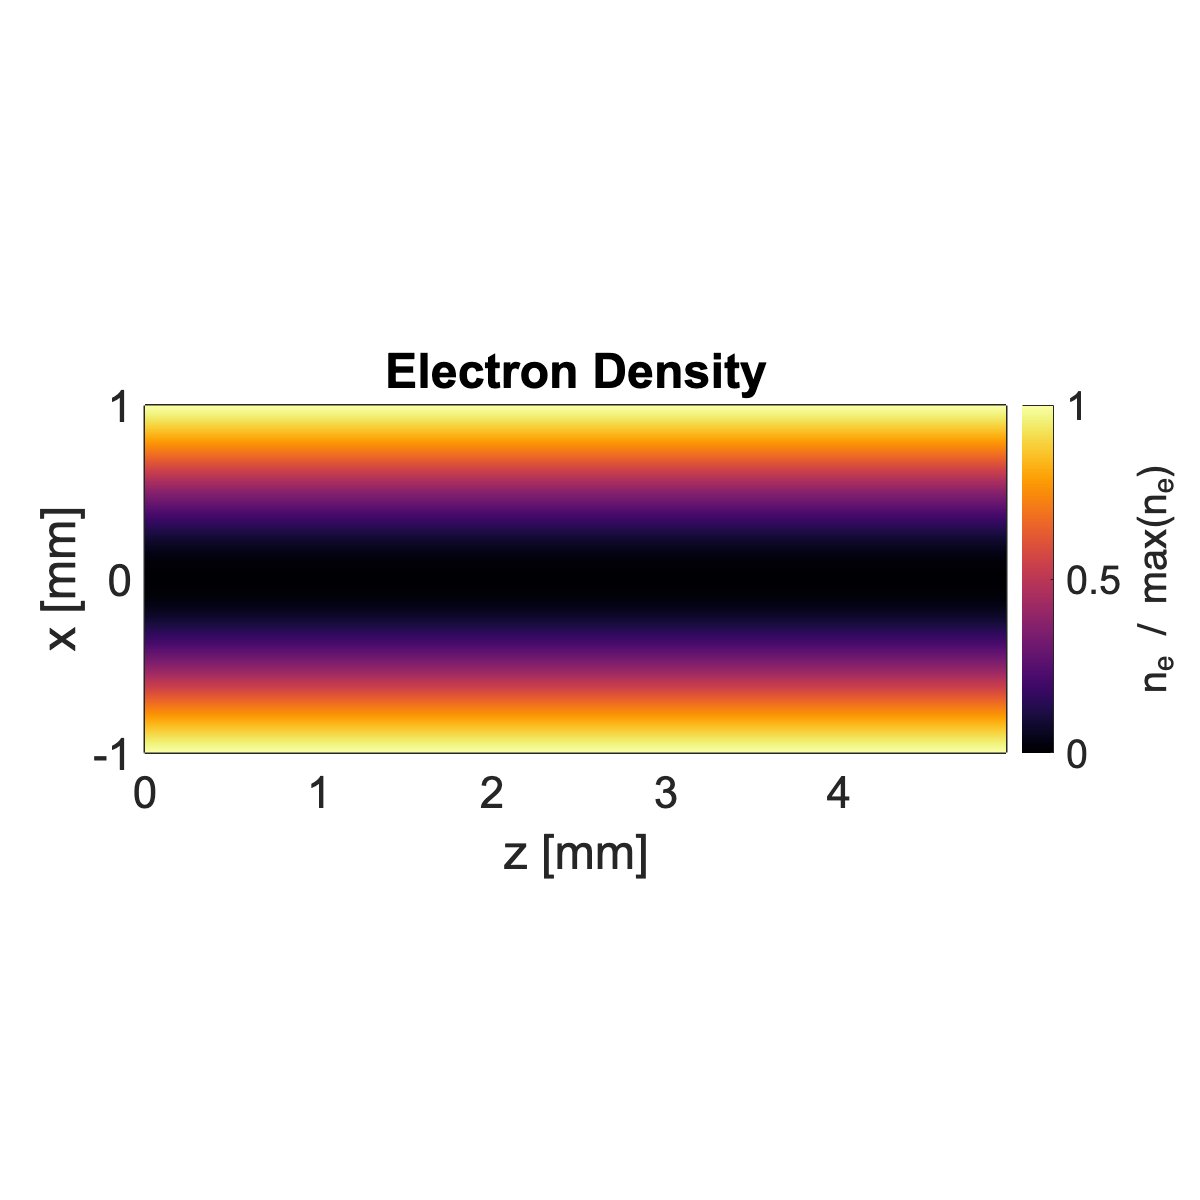


figure
show_ne(ne,t1)

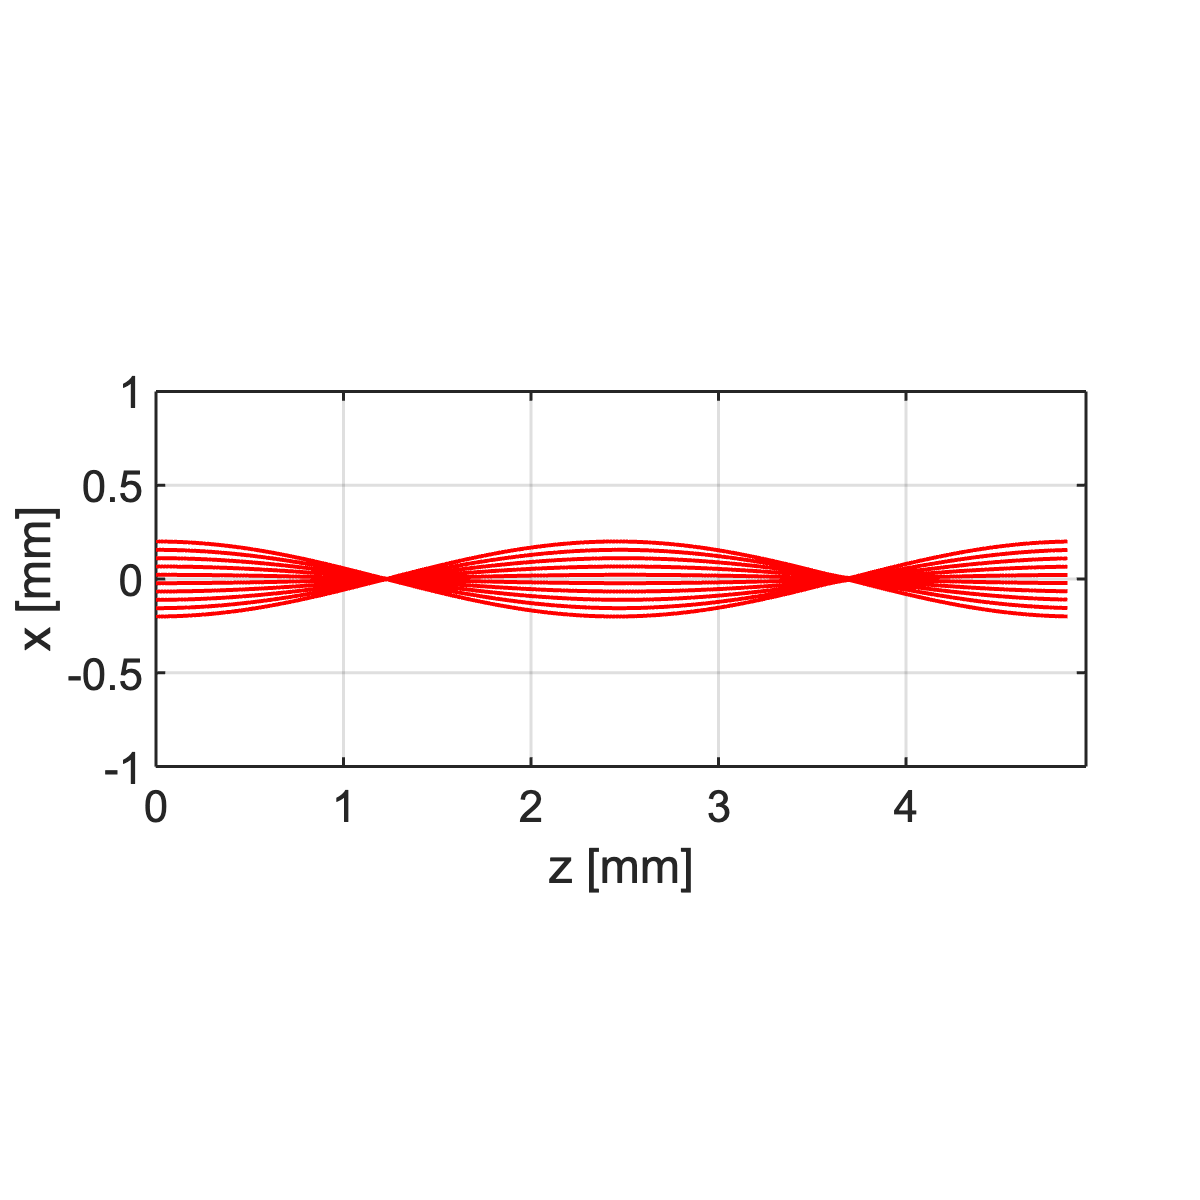


figure
t1.showResults()

% Focuser

t1 = HamTracer(532e-9,51,[-1e-3,1e-3],[0,5e-3]); % initialize tracer object

% Ref. idx (SELFOC)
A = pi / (5e-3);
nc = F.getOwavencrit(t1.lam*100); % cm^{-3}
ne = nc * (1 - (1-A^2/2 .* t1.xx.^2).^2); % cm^-3

N = t1.getOwaveN(ne); % refractive idx
t1 = t1.setN(N);

% Solve
xi = linspace(-0.5e-3,0.5e-3,10);
zi = 0 * ones(size(xi));
thi = 0 * ones(size(xi));

tmax = 20 * 2e-3 / c * 2;
t1 = t1.solve(xi,zi,thi,tmax,tmax/200);

figure
t1.showN()

figure
show_ne(ne,t1)

figure
t1.showResults()
title(['A = ' num2str(A)])
saveDir = 'Figures/'
saveas(gcf,[saveDir,'focus5.png'])


% Diverging lens

% Focuser

t1 = HamTracer(532e-9,51,[-1e-3,1e-3],[0,5e-3]); % initialize tracer object

A = pi / (9e-3);
N = 0.95 * (1 + 0.5 * A^2 * t1.xx.^2); % refractive idx
ne = nc * (1- N.^2);

N = t1.getOwaveN(ne); % refractive idx
t1 = t1.setN(N);

% Solve
xi = linspace(-0.5e-3,0.5e-3,10);
zi = 0 * ones(size(xi));
thi = 0 * ones(size(xi));

tmax = 20 * 2e-3 / c * 2;
t1 = t1.solve(xi,zi,thi,tmax,tmax/200);

figure
t1.showN()

figure
show_ne(ne,t1)

figure
t1.showResults()


% ID slab

t1 = HamTracer(532e-9,51,[-1e-3,1e-3],[0,5e-3]); % initialize tracer object

% Ref. idx (1D slab)
B = 0.96;
A = - B * 4 * 0.1e-3 / (5e-3)^2; % A = B * 4 * del_x / z^2
N = sqrt(A * t1.xx + B); % refractive idx
ne = nc * (1- N.^2);
N = t1.getOwaveN(ne);
t1 = t1.setN(N);

N = t1.getXwaveN(ne,B);

% Solve
xi = linspace(-0.5e-3,0.5e-3,10);
zi = 0 * ones(size(xi));
thi = 0 * ones(size(xi));

tmax = 20 * 2e-3 / c * 2;
t1 = t1.solve(xi,zi,thi,tmax,tmax/200);

figure
t1.showN()

figure
show_ne(ne,t1)

figure
t1.showResults()
title(['A = ' num2str(A)])
saveDir = 'Figures/'
saveas(gcf,[saveDir,'slab9.png'])

% Off-axis focuser

t1 = HamTracer(532e-9,51,[-1e-3,1e-3],[0,5e-3]); % initialize tracer object

% Ref. idx (1D slab)
B = 0.95;
A = B * 4 * 1.5e-3 / (5e-3)^2; % A = B * 4 * del_x / z^2
N1 = sqrt(A * t1.xx + B); % refractive idx
A = pi / (2e-3);
N2 = 1 * (1 - 0.5 * A^2 * t1.xx.^2); % refractive idx
N = N1 + 0.1 * N2; % refractive idx
ne = nc * (1- N.^2);
N = t1.getOwaveN(ne);
t1 = t1.setN(N);
figure
t1.showN()

% Solve
xi = linspace(-0.25e-3,0.25e-3,5);
zi = 0 * ones(size(xi));
thi = 0 * ones(size(xi));

tmax = 20 * 2e-3 / c * 2;
t1 = t1.solve(xi,zi,thi,tmax,tmax/200);

figure
t1.showN()

figure
show_ne(ne,t1)

figure
t1.showResults()


% Eaton lens

t1 = HamTracer(532e-9,401,[-1.5e-3,1.5e-3],[0,4e-3]); % initialize tracer object

% Ref. idx 

rr = (t1.xx.^2 + (t1.zz-2e-3).^2).^0.5;
a = 1.5e-3; 
N = sqrt(2 * a ./ rr - 1);
N (rr >= 1.5e-3) = sqrt(2 * a ./ 1.5e-3 - 1);
N = N - 5;

ne = nc * (1- N.^2);
N = t1.getOwaveN(ne);

t1 = t1.setN(N);


% Solve
xi = linspace(0.5e-3,1.4e-3,5) ;
zi = 0 * ones(size(xi));
thi = 0 * ones(size(xi));

tmax = 16 * 20 * 2e-3 / c * 2;
t1 = t1.solve(xi,zi,thi,tmax,tmax/400);

figure
t1.showN()
caxis([0,1])

figure
show_ne(ne,t1)


t1.showResults()
xlim([0.2,3])




function show_ne(ne,obj)
    surf(obj.zz * 1e3,obj.xx * 1e3,ne/max(ne(:))); colormap(inferno()); colorbar();
    xlabel('z [mm]');
    ylabel('x [mm]')
    view(2);
    title('Electron Density');
    shading interp
    cb = colorbar();
    ylabel(cb,'n_e / max(n_e)')
    formatPlots(600);legend('off');
    axis equal
    ylim(1e3*[min(obj.xx(:)),max(obj.xx(:))])
    xlim(1e3*[min(obj.zz(:)),max(obj.zz(:))])
end
